% Biểu diễn đồ thị
%global L
clear all
clc
n = 9;
m = 14;
d = 3;
size = 1;
rng(5);

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
H1 = H(1:5,:);
H2 = H(6:10,:);
H3 = H(11:14,:);

A12 = [1       sqrt(3)/2 0;
      sqrt(3)/2 1       0;
       0       0       0];
A13 = [0 0 0;
       0 1 0;
       0 0 1];
A23 = [2 1 0;
       1 1 0;
       0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0;
       0 0 0;
       0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H, eye(d));
L = Hbar'*W*Hbar;
H1 = [H(1:5,:); zeros(9,9)];
H2 = [zeros(5,9); H(6:10,:); zeros(4,9)];
H3 = [zeros(10,9); H(11:14,:)];
lambda = max(eig(L));
tauMax = pi/(2*lambda)

tauMax = 0.1579

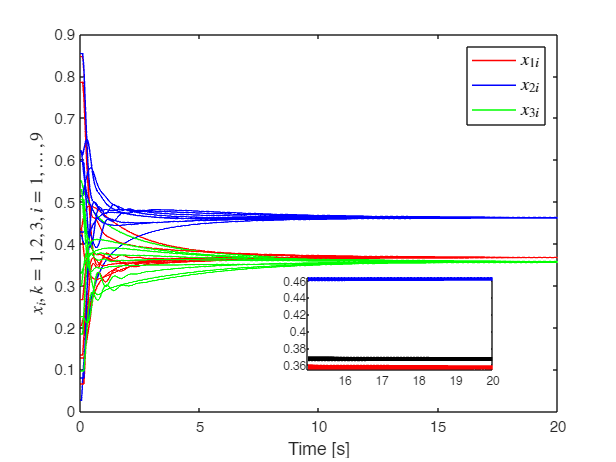

rng(2)
% Parameter initialization
t_end = 20;
x0 = rand(d*n,1);
tau1 = 0.05;
tau2 = 0.1;
tau3 = 0.15;

Hbar1 = kron(H1,eye(d));
Hbar2 = kron(H2,eye(d));
Hbar3 = kron(H3,eye(d));
L1 = Hbar1'*W*Hbar1;
L2 = Hbar2'*W*Hbar2;
L3 = Hbar3'*W*Hbar3;

% Simulink
modelName = 'c12_ConsensusMultiDelaysModel';
sim(modelName);

t = ans.yout{1}.Values.Time;
r = ans.yout{1}.Values.Data(:,1:d*n);
 
% Biểu diễn hệ
figure
hold on
plot(t, r(:,1), "LineWidth", 1, "Color", 'r');
plot(t, r(:,2), "LineWidth", 1, "Color", 'b');
plot(t, r(:,3), "LineWidth", 1, "Color", 'g');
plot(t, r(:,d+1:d:d*n), "LineWidth", 1, "Color", 'r');
plot(t, r(:,d+2:d:d*n), "LineWidth", 1, "Color", 'b');
plot(t, r(:,d+3:d:d*n), "LineWidth", 1, "Color", 'g');
legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'}, "Interpreter", "latex", "FontSize", 12)
xlabel('Time [s]',"FontSize",12)
ylabel('$x_i,~k=1,2,3,~i=1,\ldots,9$', "Interpreter", "latex", "FontSize", 12)
box on
ax = axes('position',[0.5 .2 .3 .2]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t <= 20) & (t >= 15); % range of t near perturbation
plot(t(indexOfInterest),r(indexOfInterest,d+1:d:d*n),"-k","LineWidth",2); % plot on new axes
plot(t(indexOfInterest),r(indexOfInterest,d+2:d:d*n),"-b","LineWidth",2); % plot on new axes
plot(t(indexOfInterest),r(indexOfInterest,d+3:d:d*n),"-r","LineWidth",2); % plot on new axes
axis tight
box on;

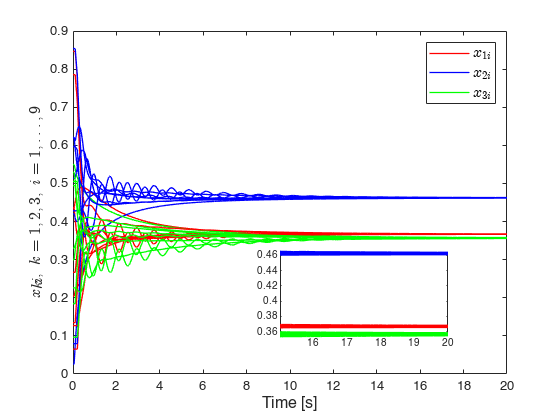

 % Simulink
 % clear all
 t_end = 20;
 tau1 = 0.05;
 tau2 = 0.1;
 tau3 = 0.20;
 
 modelName = 'c12_ConsensusMultiDelaysModel';
 sim(modelName);
 t1 = ans.yout{1}.Values.Time;
 r1 = ans.yout{1}.Values.Data(:,1:d*n);
 
 % Plot the results
 figure
 hold on
 plot(t1,r1(:,1),"LineWidth",1,"Color",'r');
 plot(t1,r1(:,2),"LineWidth",1,"Color",'b');
 plot(t1,r1(:,3),"LineWidth",1,"Color",'g');
 plot(t1,r1(:,d+1:d:d*n),"LineWidth",1,"Color",'r');
 plot(t1,r1(:,d+2:d:d*n),"LineWidth",1,"Color",'b');
 plot(t1,r1(:,d+3:d:d*n),"LineWidth",1,"Color",'g');
 legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'}, "Interpreter", "latex", "FontSize", 12)
 xlabel('Time [s]',"FontSize",12)
 ylabel('$x_{ki},~k=1,2,3,~i=1,\ldots,9$', "Interpreter", "latex", "FontSize", 12)
 box on
ax = axes('position',[0.5 .2 .3 .2]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t1 <= 20) & (t1 >= 15); % range of t near perturbation
plot(t1(indexOfInterest), r1(indexOfInterest,d+1:d:d*n),"-r","LineWidth",2); % plot on new axes
plot(t1(indexOfInterest), r1(indexOfInterest,d+2:d:d*n),"-b","LineWidth",2); % plot on new axes
plot(t1(indexOfInterest), r1(indexOfInterest,d+3:d:d*n),"-g","LineWidth",2); % plot on new axes
axis tight
box on;

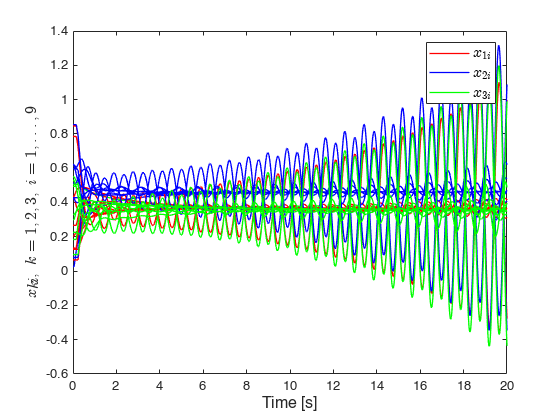

% Simulink
% clear all
t_end = 20;
tau1 = 0.05;
tau2 = 0.15;
tau3 = 0.23;

modelName = 'c12_ConsensusMultiDelaysModel';
sim(modelName);
t1 = ans.yout{1}.Values.Time;
r1 = ans.yout{1}.Values.Data(:,1:d*n);

% Plot the results
figure
hold on
plot(t1,r1(:,1),"LineWidth",1,"Color",'r');
plot(t1,r1(:,2),"LineWidth",1,"Color",'b');
plot(t1,r1(:,3),"LineWidth",1,"Color",'g');
plot(t1,r1(:,d+1:d:d*n),"LineWidth",1,"Color",'r');
plot(t1,r1(:,d+2:d:d*n),"LineWidth",1,"Color",'b');
plot(t1,r1(:,d+3:d:d*n),"LineWidth",1,"Color",'g');
legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'}, "Interpreter", "latex", "FontSize", 12)
xlabel('Time [s]',"FontSize",12)
ylabel('$x_{ki},~k=1,2,3,~i=1,\ldots,9$', "Interpreter", "latex", "FontSize", 12)
box on

% ax = axes('position',[0.5 .2 .3 .2]);
% box on  % put box around new pair of axes
% hold on
% indexOfInterest = (t1 <= 20) & (t1 >= 15); % range of t near perturbation
% plot(t1(indexOfInterest), r1(indexOfInterest,d+1:d:d*n),"-r","LineWidth",2); % plot on new axes
% plot(t1(indexOfInterest), r1(indexOfInterest,d+2:d:d*n),"-b","LineWidth",2); % plot on new axes
% plot(t1(indexOfInterest), r1(indexOfInterest,d+3:d:d*n),"-g","LineWidth",2); % plot on new axes
% axis tight
% box on;